%Calibration data
load Calibration_data_new.csv

twentyinch = mean(Calibration_data_new(:,2));
twentytwoinch = mean(Calibration_data_new(:,4));
twentyfourinch = mean(Calibration_data_new(:,6));
twentysixinch = mean(Calibration_data_new(:,8));
twentyeightinch = mean(Calibration_data_new(:,10));
thirtyinch = mean(Calibration_data_new(:,12)); %this will be our test point
thirtytwoinch = mean(Calibration_data_new(:,14));
thirtyfourinch = mean(Calibration_data_new(:,16));
thirtysixinch = mean(Calibration_data_new(:,18));
thirtyeightinch = mean(Calibration_data_new(:,20));
fourtyinch = mean(Calibration_data_new(:,22));

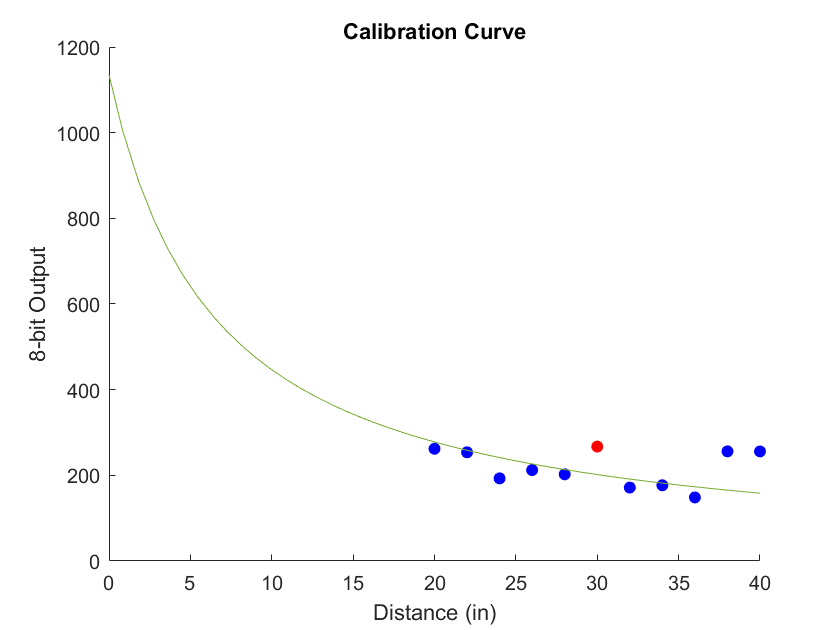

%data for finding line of best fit
bestfitx = [20, 22, 24, 26, 28, 32, 34, 36, 38, 40];
bestfity = [twentyinch, twentytwoinch, twentyfourinch, twentysixinch, twentyeightinch, thirtytwoinch, thirtyfourinch, thirtysixinch, thirtyeightinch, fourtyinch];

%equation from line of best fit
p1 = 7362;
q1 = 6.488;

%graph of data and line of best fit
figure(1)
clf; hold on
scatter(20, twentyinch, 'b', 'filled')
scatter(22, twentytwoinch, 'b', 'filled')
scatter(24, twentyfourinch, 'b', 'filled')
scatter(26, twentysixinch, 'b', 'filled')
scatter(28, twentyeightinch, 'b', 'filled')
scatter(30, thirtyinch, 'r', 'filled')
scatter(32, thirtytwoinch, 'b', 'filled')
scatter(34, thirtyfourinch, 'b', 'filled')
scatter(36, thirtysixinch, 'b', 'filled')
scatter(38, thirtyeightinch, 'b', 'filled')
scatter(40, fourtyinch, 'b', 'filled')
fplot(@(x) (p1)./(x+q1))
xlabel("Distance (in)")
xlim([0 40])
ylabel("8-bit Output")
title("Calibration Curve")


%Sensing and Graphing

%load data
load test1.csv

theta = test1(:,1); %horizontal angle
rho = test1(:,2); %vertical angle
bit_distance = test1(:,3); %distance as an 8-bit output

%convert from 8-bit output to distance using y = (7362)./(x+6.488)
% --> x = 7362/y - 6.488
distance = 7362./bit_distance - 6.488 %inches

distance =   173.0730
  108.5433
  140.7520
  101.7767
  173.0730
   90.3804
   90.3804
   11.5561
   11.5120
   16.0258


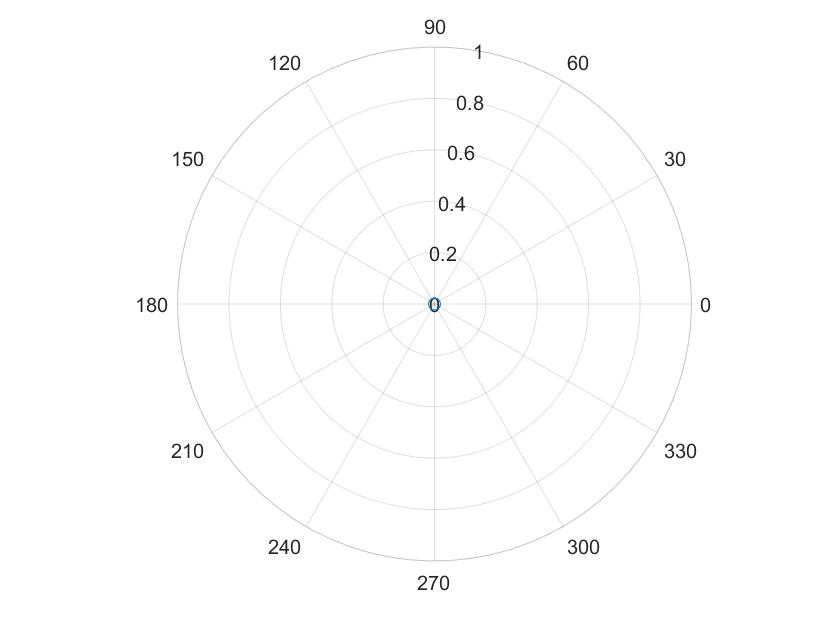


%plot the data on a polar graph
figure
polarscatter(theta, rho)


%convert to Cartesian and plot
[x,y] = pol2cart(theta, rho);
tbl = table(x, y, distance)

tbl = 91×3 table
    x    y    distance
    _    _    ________

    0    0     173.07 
    0    0     108.54 
    0    0     140.75 
    0    0     101.78 
    0    0     173.07 
    0    0      90.38 
    0    0      90.38 
    0    0     11.556 
    0    0     11.512 
    0    0     16.026 
    0    0     5.5218 
    0    0     7.7244 
    0    0     7.1453 
    0    0      6.249 
    0    0     5.7616 
    0    0     6.1615 


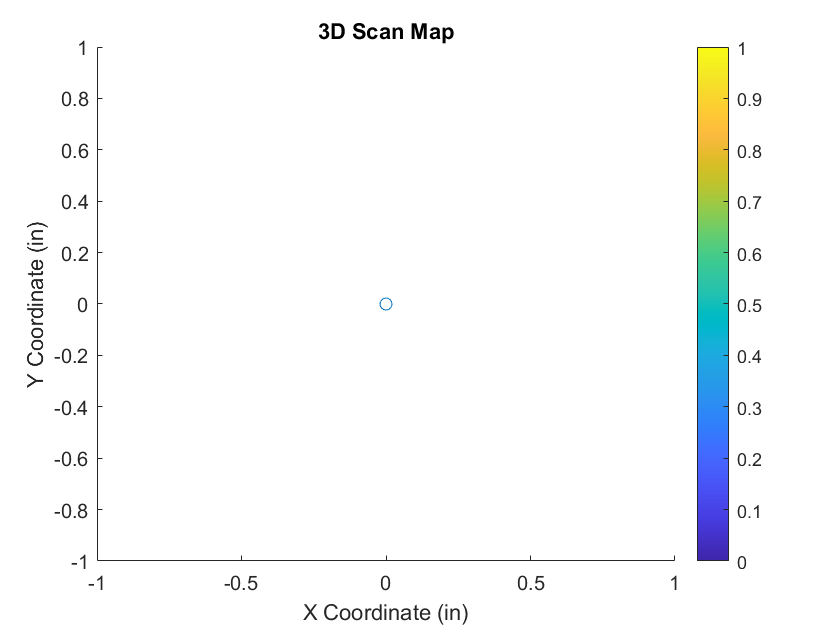


figure
clf; hold on
scatter(x,y)
%scatter(tbl, 'x', 'y', 'distance')
xlabel('X Coordinate (in)')
ylabel('Y Coordinate (in)')
title('3D Scan Map')
colorbar